clear; clc; close all;

%% Define pickup points (using your naming convention)

% Shim offsets
clevisOriginOffset = [0, 0, 0];
nominalCamberShim = [0, 6.6, 0];
clevisShimOffsetUFA = [0, 9, 0];
clevisShimOffsetUAA = [0, 9, 0];
clevisShimOffsetLFA = [0, 9, 0];
clevisShimOffsetLAA = [0, 9, 0];
uprightConnector = [0, 82.5, 0];
GEN3_KinematicParameters

vehicle = struct with fields:
    ford: [1×1 struct]


vehicle = struct with fields:
    ford: [1×1 struct]


vehicle = struct with fields:
    ford: [1×1 struct]


vehicle = struct with fields:
    ford: [1×1 struct]


vehicle = struct with fields:
      ford: [1×1 struct]
        GM: [1×1 struct]
    toyota: [1×1 struct]


vehicle = struct with fields:
      ford: [1×1 struct]
        GM: [1×1 struct]
    toyota: [1×1 struct]


% Upper A-Arm
params.upperAArm.fore = vehicle.ford.kinematics.rear.upperAArm.fore 

params = struct with fields:
    upperAArm: [1×1 struct]


params.upperAArm.aft = vehicle.ford.kinematics.rear.upperAArm.aft 

params = struct with fields:
    upperAArm: [1×1 struct]


params.upperAArm.ballJoint = vehicle.ford.kinematics.rear.upperAArm.ballJoint

params = struct with fields:
    upperAArm: [1×1 struct]



% Lower A-Arm
params.lowerAArm.fore = vehicle.ford.kinematics.rear.lowerAArm.fore + clevisOriginOffset 

params = struct with fields:
    upperAArm: [1×1 struct]
    lowerAArm: [1×1 struct]


params.lowerAArm.aft = vehicle.ford.kinematics.rear.lowerAArm.aft + clevisOriginOffset 

params = struct with fields:
    upperAArm: [1×1 struct]
    lowerAArm: [1×1 struct]


params.lowerAArm.ballJoint = vehicle.ford.kinematics.rear.lowerAArm.ballJoint;

% Toe Rod
toeRodParams.chassis = vehicle.ford.kinematics.rear.lowerAArm.toeRodChassis;
toeRodParams.upright = vehicle.ford.kinematics.rear.lowerAArm.toeRodUpright;

% Wheel Center (adjust to your actual value)
% This should be on the spindle axis, at known offset from ball joints
params.wheelCenter = vehicle.ford.kinematics.rear.upright.rotationAxis;  % <-- UPDATE THIS

%% Step 1: Solve camber
fprintf('Solving camber...\n');

Solving camber...


camberResults = solveWheelCamber(params, []);

%% Step 2: Solve toe
fprintf('Solving toe...\n');

Solving toe...


toeResults = solveWheelToe(camberResults, toeRodParams);



% Calculate Roll centre

[RC_height_array, dRC_dz_nominal] =  calculateRollCenter(camberResults.UBJ, camberResults.LBJ, ...
    camberResults.wheelTravel, vehicle)

RC_height_array =  -199.6472
 -197.6544
 -195.7007
 -193.7839
 -191.9019
 -190.0528
 -188.2345
 -186.4454
 -184.6835
 -182.9473


dRC_dz_nominal = 0.5617

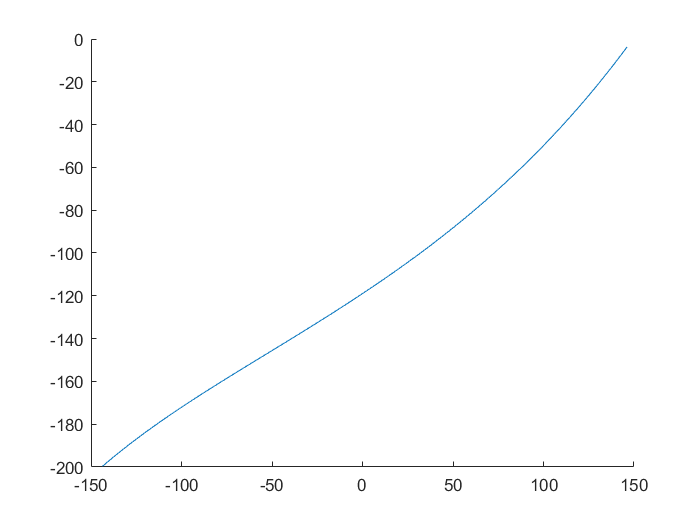

figure
hold on
plot(camberResults.wheelTravel, RC_height_array)
hold off

antDive = calculateAntiGeometry(camberResults.wheelTravel, vehicle, 'rideHeight', camberResults.LBJ)

antDive =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


idx_ride = find(abs(camberResults.wheelTravel) == min(abs(camberResults.wheelTravel)), 1);
fprintf('\n--- DEBUG INFO ---\n');


--- DEBUG INFO ---


fprintf('KPI axis at ride: [%.4f, %.4f, %.4f]\n', camberResults.KPI_axis(idx_ride, :));

KPI axis at ride: [0.0000, -0.0833, 0.9965]


fprintf('Initial toe angle: %.2f deg\n', toeResults.toe(idx_ride));

Initial toe angle: 0.00 deg



%% Display results
[~, idx_ride] = min(abs(camberResults.wheelTravel));

fprintf('\n============================================\n');

fprintf('         KINEMATICS RESULTS                \n');

         KINEMATICS RESULTS                


fprintf('============================================\n\n');


fprintf('--- At Ride Height ---\n');

--- At Ride Height ---


fprintf('  Wheel Travel: %.2f mm\n', camberResults.wheelTravel(idx_ride));

  Wheel Travel: -0.00 mm


fprintf('  Camber:       %+.3f deg\n', camberResults.camber(idx_ride));

  Camber:       -4.776 deg


fprintf('  Camber Gain:  %+.4f deg/mm\n', camberResults.camberGain(idx_ride));

  Camber Gain:  -0.0301 deg/mm


fprintf('  Toe:          %+.3f deg\n', toeResults.toe(idx_ride));

  Toe:          +0.000 deg


fprintf('  Toe Gain:     %+.4f deg/mm\n', toeResults.toeGain(idx_ride));

  Toe Gain:     -0.0013 deg/mm




fprintf('\n--- Link Lengths ---\n');


--- Link Lengths ---


fprintf('  Upright:  %.2f mm\n', camberResults.L_upright);

  Upright:  284.38 mm


fprintf('  Toe Rod:  %.2f mm\n', toeResults.toeRodLength);

  Toe Rod:  430.43 mm


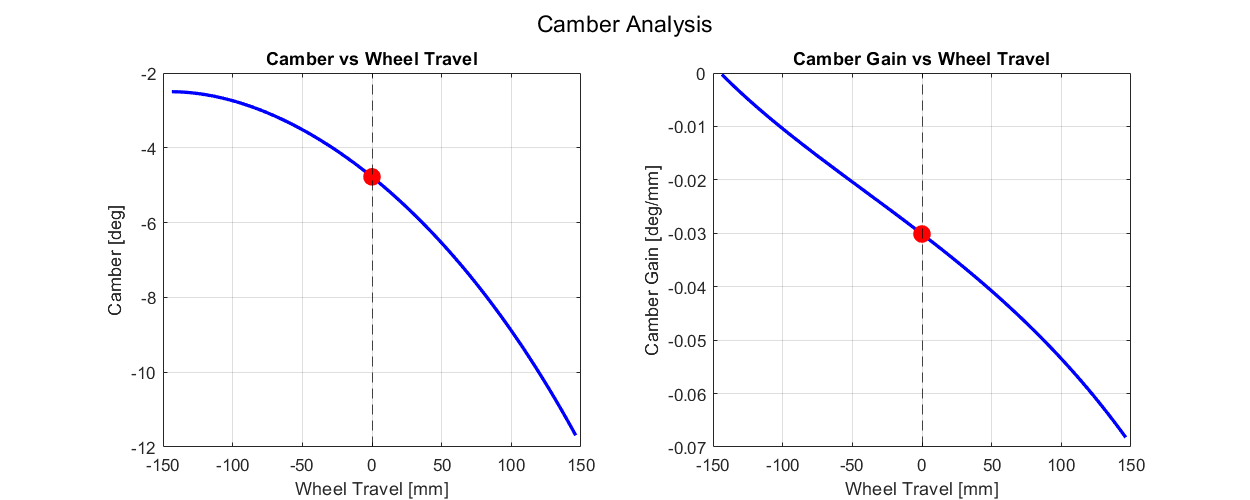


%% Plot camber results
figure('Name', 'Camber Kinematics', 'Position', [100, 100, 1000, 400]);

subplot(1, 2, 1);
plot(camberResults.wheelTravel, camberResults.camber, 'b-', 'LineWidth', 2);
hold on;
plot(camberResults.wheelTravel(idx_ride), camberResults.camber(idx_ride), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
grid on;
xlabel('Wheel Travel [mm]');
ylabel('Camber [deg]');
title('Camber vs Wheel Travel');
xline(0, '--k');

subplot(1, 2, 2);
plot(camberResults.wheelTravel, camberResults.camberGain, 'b-', 'LineWidth', 2);
hold on;
plot(camberResults.wheelTravel(idx_ride), camberResults.camberGain(idx_ride), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
grid on;
xlabel('Wheel Travel [mm]');
ylabel('Camber Gain [deg/mm]');
title('Camber Gain vs Wheel Travel');
xline(0, '--k');

sgtitle('Camber Analysis');

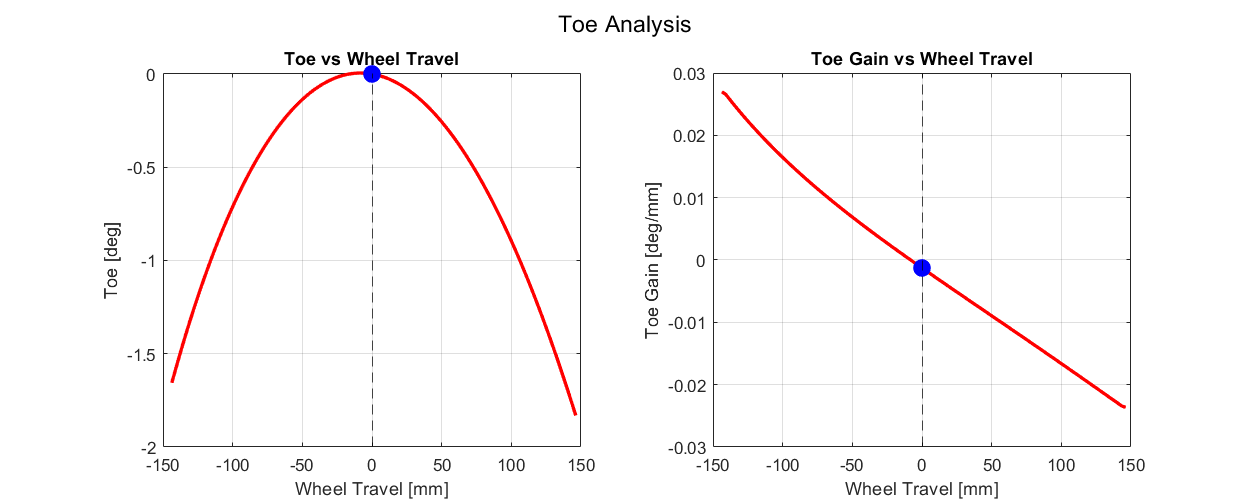


%% Plot toe results (if valid)
if ~all(isnan(toeResults.toe))
    figure('Name', 'Toe Kinematics', 'Position', [150, 150, 1000, 400]);
    
    subplot(1, 2, 1);
    plot(camberResults.wheelTravel, toeResults.toe, 'r-', 'LineWidth', 2);
    hold on;
    plot(camberResults.wheelTravel(idx_ride), toeResults.toe(idx_ride), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    grid on;
    xlabel('Wheel Travel [mm]');
    ylabel('Toe [deg]');
    title('Toe vs Wheel Travel');
    xline(0, '--k');
    
    subplot(1, 2, 2);
    plot(camberResults.wheelTravel, toeResults.toeGain, 'r-', 'LineWidth', 2);
    hold on;
    plot(camberResults.wheelTravel(idx_ride), toeResults.toeGain(idx_ride), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    grid on;
    xlabel('Wheel Travel [mm]');
    ylabel('Toe Gain [deg/mm]');
    title('Toe Gain vs Wheel Travel');
    xline(0, '--k');
    
    sgtitle('Toe Analysis');
else
    warning('Toe solution invalid - check toe rod geometry');
end

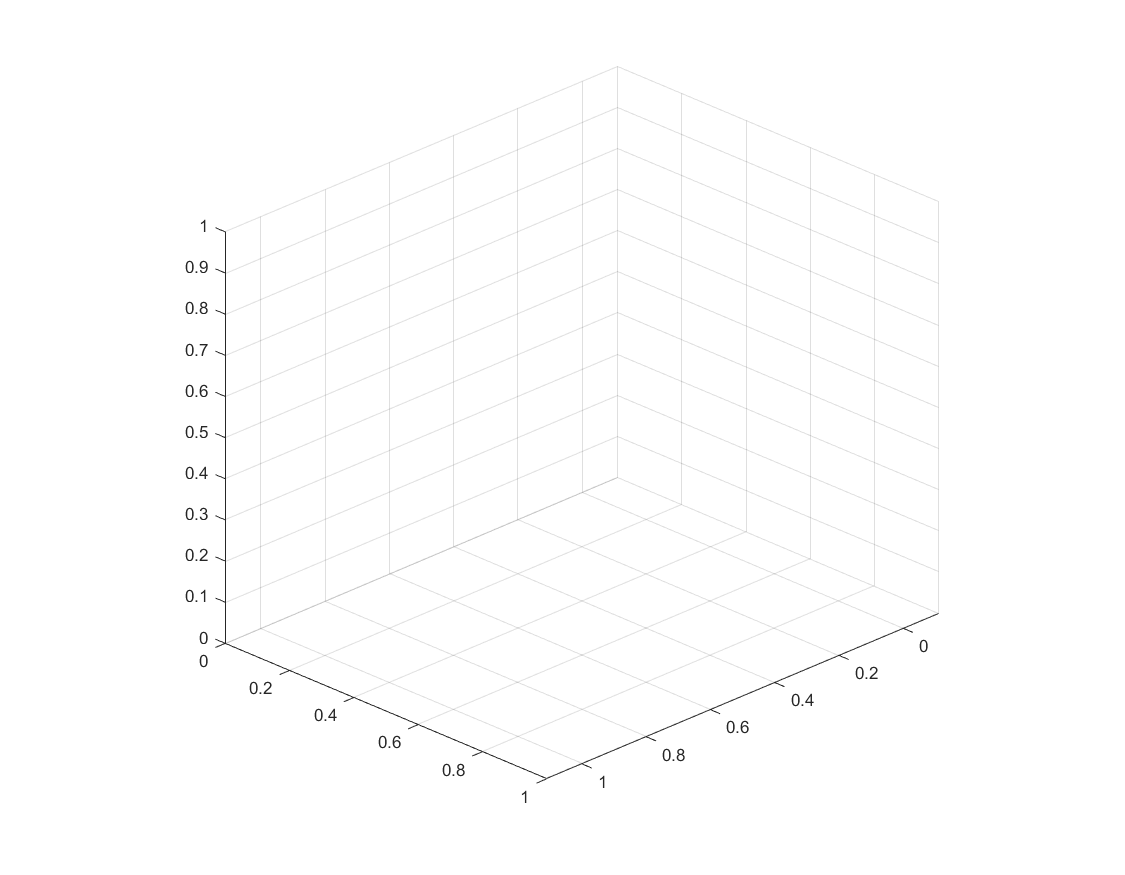


%% 3D Visualization
figure('Name', '3D Geometry', 'Position', [200, 200, 900, 700]);
hold on; grid on; axis equal;
view(135, 25);


% Chassis pivots